# Train a Long Short-Term Memory Network for Predicting Displacement of CNC Machine Centre using Temperature Sensor Data

Use a Long Short-Term Memory (LSTM) network to predict z-axis error due to the thermal deformation of CNC machine tools.

% load data files for use with several Deep Learning apps
clear; clc; close all;


% change the file path to load a different csv file
if strcmp(filesep,'\')
datapath = "C:\Users\Mareim\OneDrive - Coventry University\Data\Data on CNC temp\data\2017-03-07.csv";
else
  datapath =   "/home/mareim/MATLAB_DRIVE/NewSandbox/CNC Timeseries Data Case Study/data/";
end
dateOfDay = extractBetween(datapath,"data\",".csv");

[tsdata, ndata] = importfile1(datapath, [2, Inf]);
interval = 1:size(tsdata,1);
tsdata_interval = tsdata(interval,:);
tt1 =  table2timetable(tsdata_interval);
% fix date and time
t = tsdata.Time;
d = datetime(dateOfDay);
t.Year = d.Year;
t.Month = d.Month;
t.Day = d.Day;


% Response and predictor (temperature sensor feeds) variables (pre-normalised)


X_pre = tsdata.X(interval);
Y_pre = tsdata.Y(interval);
Z_pre = tsdata.Z(interval);


predictors_pre = tsdata{interval,5:end};% 
ts_1 = tsdata(interval,1);
% Response and predictor variables (post-normalised)

Xval = ndata.X;
Yval = ndata.Y;
Zval = ndata.Z;

%predictors = [interval, ndata{:,4:end}];
predictors = ndata{:,4:end};
% take a sample sensor as input (column 1:48 specifying sensor location in
% 6x8 grid; column 49:52 specifying sensor 1:4 around the spindle)
pred1 = predictors(:,6);

% Plot figures
ts_interval = tsdata.Time(interval);
d = datetime(dateOfDay);
ts_interval.Year = d.Year;
ts_interval.Month = d.Month;
ts_interval.Day = d.Day;

%plotdata();

### Split the dataset into training and testing data

Create three two-hour-long sampling intervals, with random starting points

numSamplingIntervals = 3;
% calculate the length of each sample such that 25% of the timeseries is
% used for testing
numHours = t.Hour(end)-t.Hour(1)+1;
samplingMinutes = 0.25*numHours*120;
sampleDuration = samplingMinutes/numSamplingIntervals;
%startTimes = sort(randsample(numHours-3,numSamplingIntervals,false))*sampleDuration;
% assign random start points for sampling 
%startTimes = abs(startTimes(:) - 2*randsample(45,numSamplingIntervals))
% ensure that this value doesn't exceed the maximum time prediction 
for i = 1:numSamplingIntervals
    rangeStartpoint = ceil((i-1)*numHours*sampleDuration/(2*numSamplingIntervals))
    rangeEndpoint = ceil(i*numHours*sampleDuration/(2*numSamplingIntervals))
    startTimes(i) = randsample(rangeStartpoint:rangeEndpoint,1,true)
end

rangeStartpoint = 0

rangeEndpoint = 960

startTimes =          526        1797        1947


rangeStartpoint = 960

rangeEndpoint = 1920

startTimes =          526        1108        1947


rangeStartpoint = 1920

rangeEndpoint = 2880

startTimes =          526        1108        2190


startTimes = sort(startTimes)

startTimes =          526        1108        2190


endTimes = startTimes(:) + sampleDuration

endTimes =          766
        1348
        2430


### Generate a subset of testing samples

Add an index to predictors so the desired data points can be selected by their relative index in the input data. 

predictors(:,1);

for i = 1:numSamplingIntervals
    % calculate sampling interval duration
    intervalPoints = startTimes(i):endTimes(i); 
    ezs = [intervalPoints', Zval(intervalPoints')];
    newStartPoint = startTimes(i);
    % starting at the first point in the interval + the interval
    newEndPoint = newStartPoint + intervalPoints(end);
    eps = [predictors(startTimes(i):endTimes(i),:)];
    % set new start index
    startIndex = 1+(i-1)*sampleDuration
    extZSamples(startIndex:startIndex+sampleDuration,:) = ezs;
    extPredSamples(startIndex:startIndex+sampleDuration,:) = eps;
    %extPredSample() = eps;
    %Ztest((i-1)*240+1:i*240+i,1) = extSample;
end

startIndex = 1

startIndex = 241

startIndex = 481

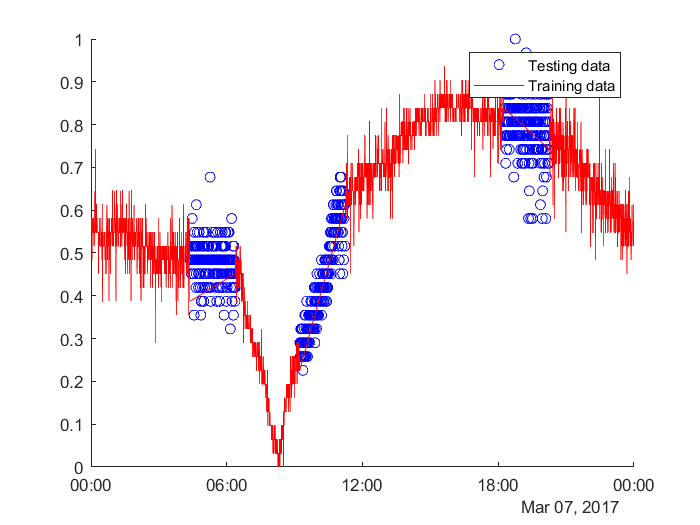

predictors_test =  extPredSamples;
predictors_train = predictors;
indexesToRemove = extZSamples(:,1);
% remove indexes in indexesToRemove
predictors_train(indexesToRemove,:) =  [];
% similarly, remove indexes in Zvals_train
Zvals_test = extZSamples;
Zvals_train = [interval', Zval];
Zvals_train(indexesToRemove,:) = [];

figure(3); clf reset;
testIndeces = Zvals_test(:,1);
trainIndeces = Zvals_train(:,1);
scatter(t(testIndeces),Zvals_test(:,2),'b');
hold on;
plot(t(trainIndeces),Zvals_train(:,2),'r');
legend('Testing data','Training data');

## Step 1: Feature selection for regression using Neighborhood Component Analysis 

Create a Feature Selection for Regression Neighborhood Component Analysis (FSRNCA) model to weight each feature based on a predefined threshold \Lambda, equal to 0.5/numObservations

lambda = 0.5/size(Zvals_train,2);
mdl = fsrnca(predictors_train, Zvals_train(:,2),'Verbose',1,'FitMethod','Exact','Solver','lbfgs');


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  7.962853e-02 |   2.370e-03 |   0.000e+00 |        |   2.532e+02 |   0.000e+00 |   YES  |
|        1 |  7.677420e-02 |   6.361e-04 |   1.101e+00 |    OK  |   1.876e+02 |   1.000e+00 |   YES  |
|        2 |  7.477934e-02 |   5.801e-04 |   9.882e-01 |    OK  |   5.682e+02 |   1.000e+00 |   YES  |
|        3 |  7.138958e-02 |   1.229e-03 |   2.578e+00 |    OK  |   1.184e+03 |   1.000e+00 |   YES  |
|        4 |  6.980139e-02 |   5.954e-04 |   1.304e+00 |    OK  |   7.459e+02 |   1.000e+00 |   YES  |
|        5 |  6.890075e-02 |   2.807e-04 |   1.251e+00 |    OK  |   5.200e+02 |   1.000e+00 |   YES  

[fi,fj,fs]  = find(mdl.FeatureWeights > 2*lambda);

## Plot the results

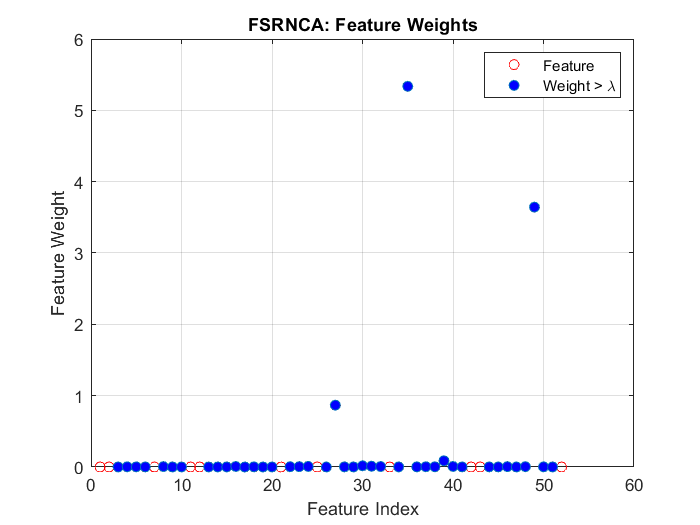

figure(2); clf reset;
plot(mdl.FeatureWeights,'ro');
hold on;
scatter(fi,mdl.FeatureWeights(fi),'MarkerFaceColor','b');
legend('Feature','Weight > \lambda');
xlabel('Feature Index');
ylabel('Feature Weight');
grid on;
title('FSRNCA: Feature Weights');

## Approach 2: Use the Diagnostic Feature Designer App to generate condition indicators

TODO

## Approach 3: Use a simple LSTM layer to predict the output of the z-axis displacement taking in the file ensemble datastore as input

% Training Data
XTrain = predictors_train';
YTrain = Zvals_train(:,2:end)';
% Testing Data
XTest = predictors_test';
YTest = Zvals_test(:,2:end)';

numFeatures = 52;
numHiddenUnits = 250;
numResponses = 1;

layers = [... 
    sequenceInputLayer(numFeatures),...
    lstmLayer(numHiddenUnits,'OutputMode','sequence'),...
    fullyConnectedLayer(180),...
    dropoutLayer(0.4),...
    fullyConnectedLayer(numResponses),...
    regressionLayer;
    ];
options = trainingOptions('adam', ...
    'MaxEpochs',150, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.0025, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.125, ...
    'Verbose',0, ...
    "ValidationData",[{XTest},{YTest}],...
    "ValidationFrequency",20,...
    'Plots','training-progress');

### Designate the training and testing data and pre-train the model

Vary the training options to improve the performance, or try training the model for longer.

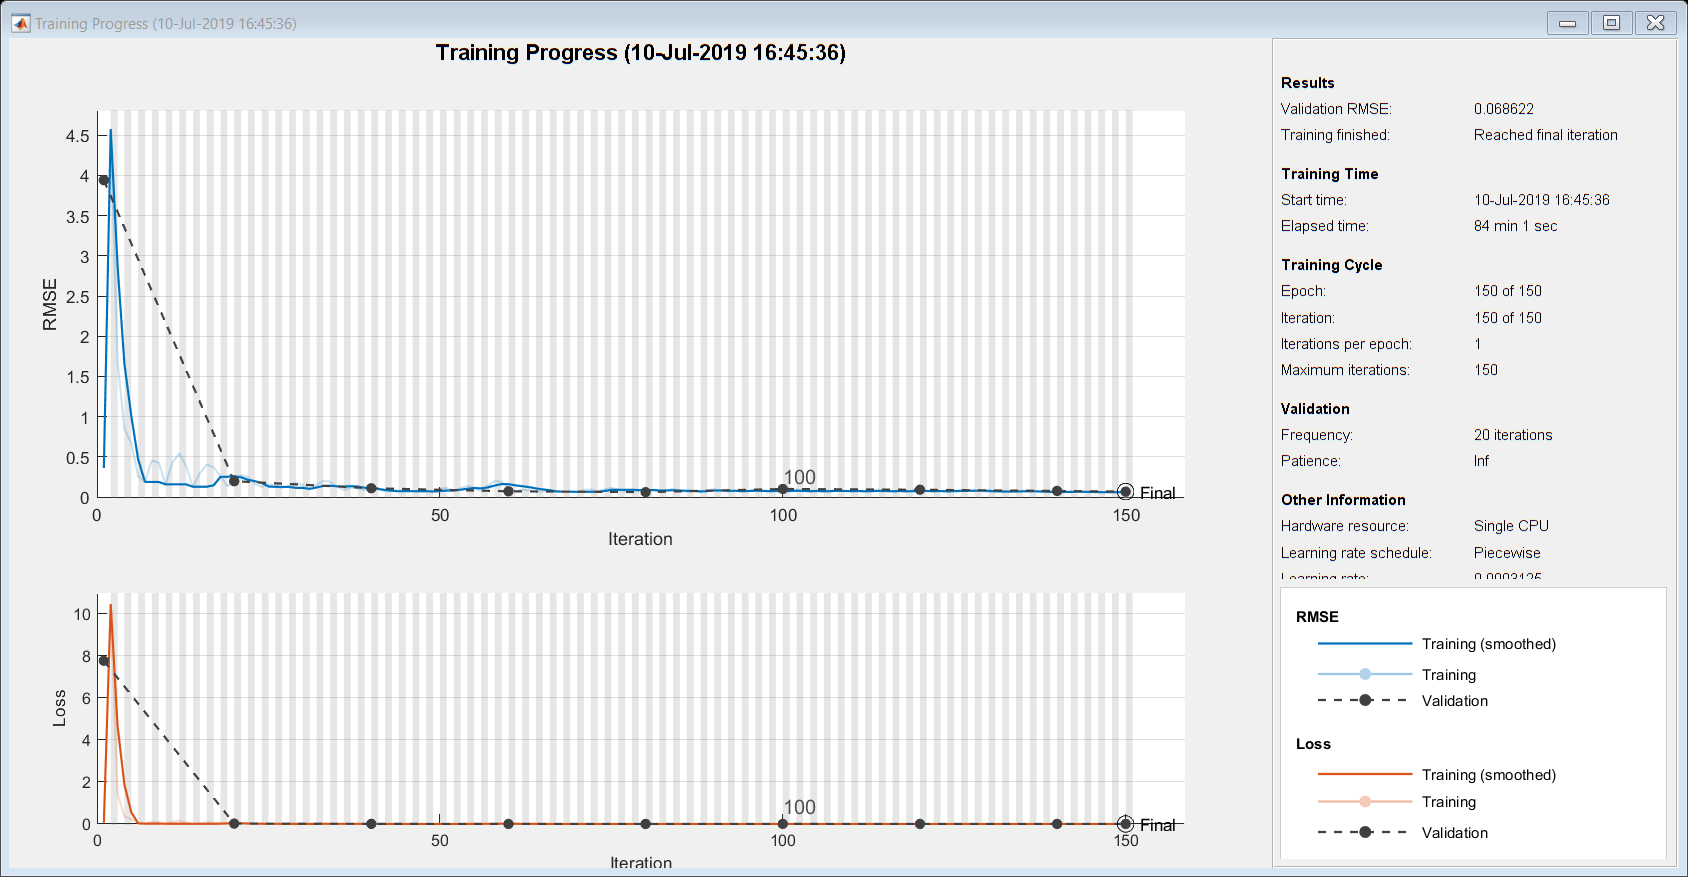

net = trainNetwork(XTrain, YTrain, layers, options);


YPred = predict(net,XTest,'MiniBatchSize',1);

## Plot the results

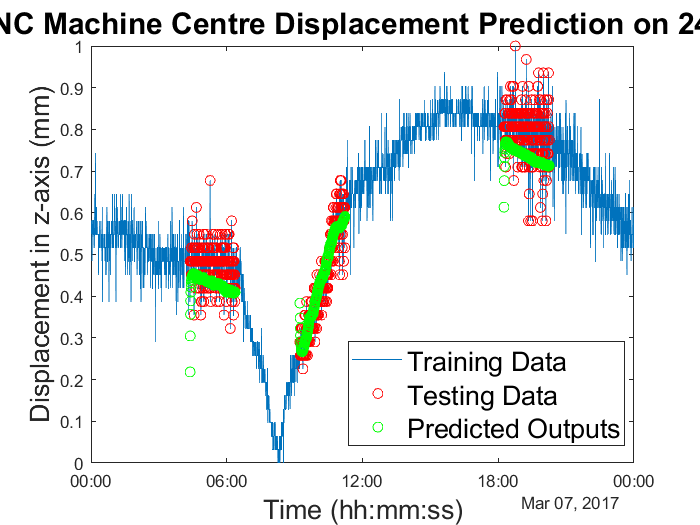

testData = [{t(testIndeces)},{YTest}];
predData = [{t(testIndeces)},{YPred}];

% Create a figure to show the prediction outputs
figure(4); clf reset;
plot(t,Zval(:,1));
hold on
scatter(testData{:,1},testData{:,2},'r');
scatter(predData{:,1},predData{:,2},'g');
hold off
legend('Training Data','Testing Data','Predicted Outputs','Location','Best','FontSize',16)
ylabel('Displacement in z-axis (mm)','FontSize',16);
xlabel('Time (hh:mm:ss)','FontSize',16);
title('LSTM z-axis CNC Machine Centre Displacement Prediction on 24-hour Sequence','FontSize',18);

% calculate RMSE and display it in the histogram for all
% predictions
RMSE = sqrt(mean((YPred - YTest).^2))

RMSE = single
0.0686

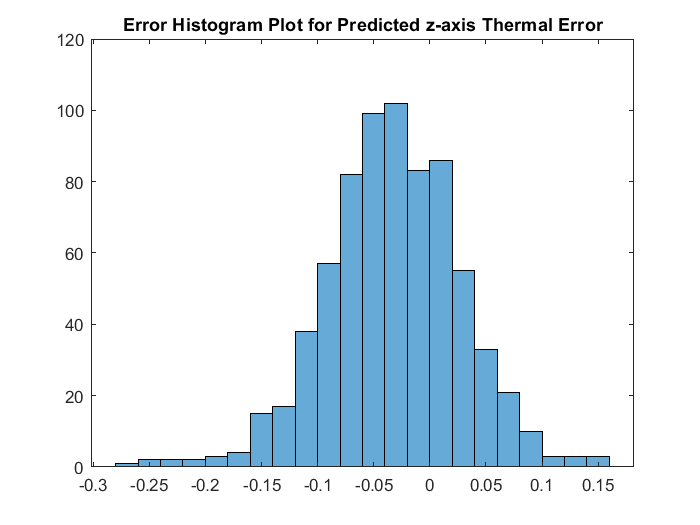

figure(4); clf reset;
h1 = histogram(YPred - YTest);
title('Error Histogram Plot for Predicted z-axis Thermal Error');


acc_t = [0.10 0.20];
errors = abs(YPred - YTest);
% accuracy of estimation error magnitude
numCorrect_1 = errors(errors < acc_t(1));
numCorrect_2 = errors(errors < acc_t(2));
acc_10 = size(numCorrect_1,2)/size(YPred,2)

acc_10 = 0.8710

acc_20 = size(numCorrect_2,2)/size(YPred,2)

acc_20 = 0.9903

## Approach 3b: Use only the features identified from FSRNCA implementation

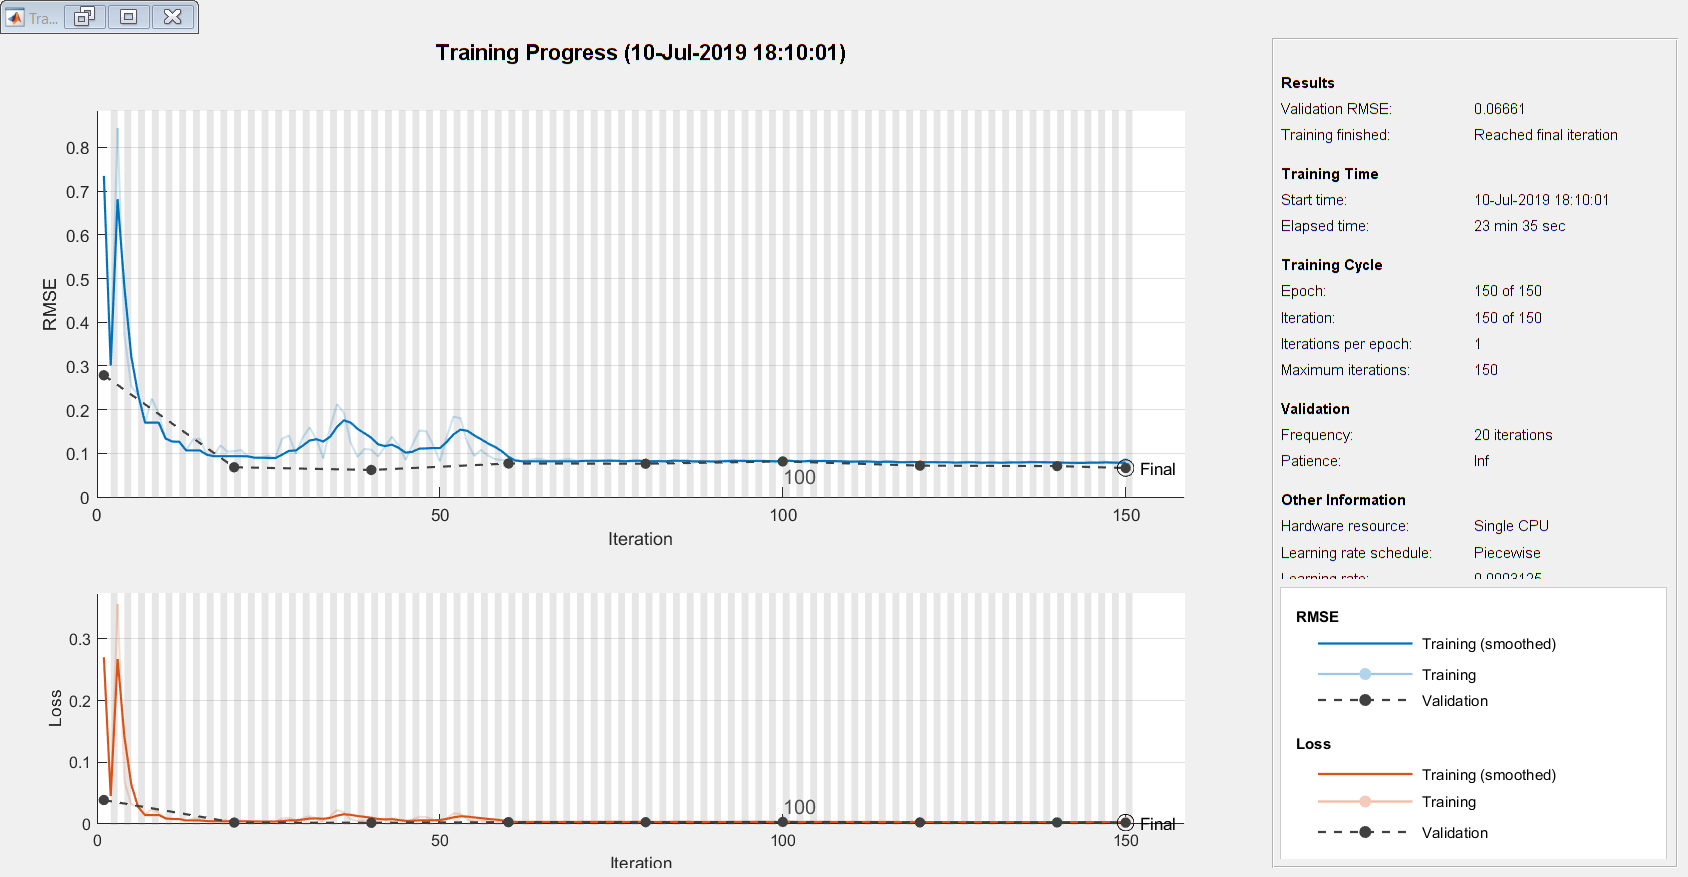

% Training Data
fsrnca_features = fi;
XTrain_fsrnca = predictors_train(:,fsrnca_features)';
YTrain = Zvals_train(:,2:end)';
% Testing Data
XTest_fsrnca = predictors_test(:,fsrnca_features)';
YTest_fsrnca = Zvals_test(:,2:end)';

numFeatures_fsrnca = size(fi,1);
%numHiddenUnits = 250;
numResponses = 1;

layers = [... 
    sequenceInputLayer(numFeatures_fsrnca),...
    lstmLayer(numHiddenUnits,'OutputMode','sequence'),...
    fullyConnectedLayer(180),...
    reluLayer(),... 
    dropoutLayer(0.4),...
    fullyConnectedLayer(numResponses),...
    regressionLayer;
    ];
options = trainingOptions('adam', ...
    'MaxEpochs',150, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.0025, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.125, ...
    'Verbose',0, ...
    "ValidationData",[{XTest_fsrnca},{YTest_fsrnca}],...
    "ValidationFrequency",20,...
    'Plots','training-progress');

net2 = trainNetwork(XTrain_fsrnca, YTrain, layers, options);


YPred_fsrnca = predict(net2,XTest_fsrnca,'MiniBatchSize',1);

## Plot the results

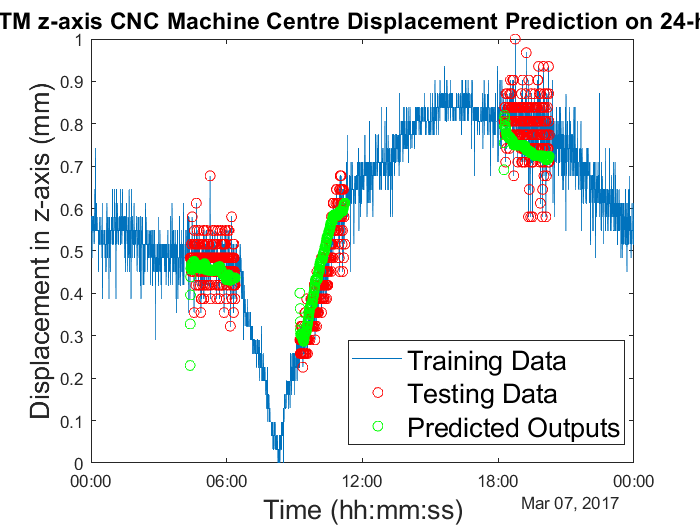

testData_fsrnca = [{t(testIndeces)},{YTest}];
predData_fsrnca = [{t(testIndeces)},{YPred_fsrnca}];

% Create a figure to show the prediction outputs
figure(5); clf reset;
plot(t,Zval(:,1));
hold on
scatter(testData_fsrnca{:,1},testData_fsrnca{:,2},'r');
scatter(predData_fsrnca{:,1},predData_fsrnca{:,2},'g');
hold off
legend('Training Data','Testing Data','Predicted Outputs','Location','Best','FontSize',16)
ylabel('Displacement in z-axis (mm)','FontSize',16);
xlabel('Time (hh:mm:ss)','FontSize',16);
title('FSRNCA-LSTM z-axis CNC Machine Centre Displacement Prediction on 24-hour Sequence','FontSize',14);

% calculate RMSE and display it in the histogram for all
% predictions
RMSE_fsrnca = sqrt(mean((YPred_fsrnca - YTest_fsrnca).^2))

RMSE_fsrnca = single
0.0666

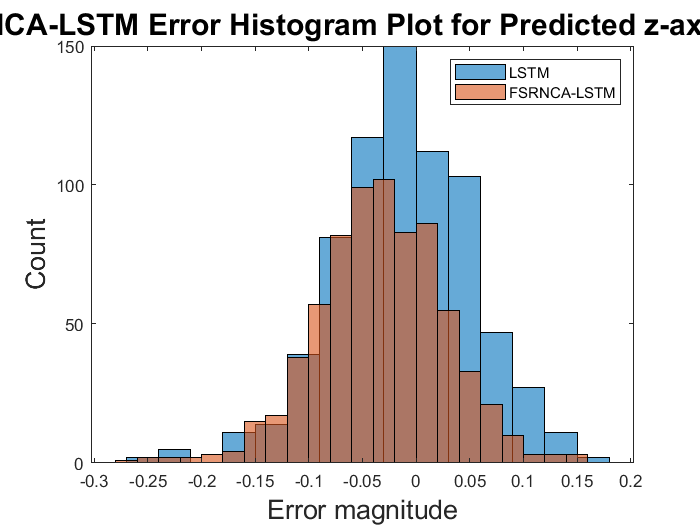

figure(6); clf reset;
h1 = histogram(YPred_fsrnca - YTest_fsrnca);
hold on;
h2 = histogram(YPred - YTest);
legend('LSTM','FSRNCA-LSTM')
title('LSTM vs FSRNCA-LSTM Error Histogram Plot for Predicted z-axis Thermal Error',"FontSize",18)
xlabel("Error magnitude","FontSize",16)
ylabel("Count","FontSize",16)

acc_t = [0.10 0.20];
errors_fsrnca = abs(YPred_fsrnca - YTest_fsrnca);
% accuracy of estimation error magnitude
numCorrect_1_fsrnca = errors_fsrnca(errors_fsrnca < acc_t(1));
numCorrect_2_fsrnca = errors_fsrnca(errors_fsrnca < acc_t(2));
acc_10_fsrnca = size(numCorrect_1_fsrnca,2)/size(YPred_fsrnca,2)

acc_10_fsrnca = 0.8724

acc_20_fsrnca = size(numCorrect_2_fsrnca,2)/size(YPred_fsrnca,2)

acc_20_fsrnca = 0.9903

As observed, we can increase the validation accuracy by 0.95% when using FSRNCA. Tuning this quantity further could help us further improve the prediction performance.

%RMSE_fsrnca = sqrt(mean(YPred_fsrnca - YTest_fsrnca.^2))

acc_gain = [-acc_10 + acc_10_fsrnca, -acc_20 + acc_20_fsrnca]

acc_gain =     0.0014         0



Performance = [acc_10 acc_20 RMSE]

Performance = 1×3 single row vector
    0.8710    0.9903    0.0686


Performance_fsrnca = [acc_10_fsrnca acc_20_fsrnca RMSE_fsrnca]

Performance_fsrnca = 1×3 single row vector
    0.8724    0.9903    0.0666
